# Synthetic Data FacTBRK experiments


close all
clear all
addpath('../tproduct toolbox 2.0 (transform)/')
warning('off','all')

%To-do: implement trial averaging, try different inner block sizes, do
%experiment for all other combinations of system sizes

First, we'll generate a tensor linear system.

- U underdetermined (m < m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)

%fixed:
p = 30;
n = 10;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_1 = 20;

%U underdetermined (m < m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)--Works
m = 10;
m_2 = 15;


U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V);

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B = tprod(U, Z_ddagg);




Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

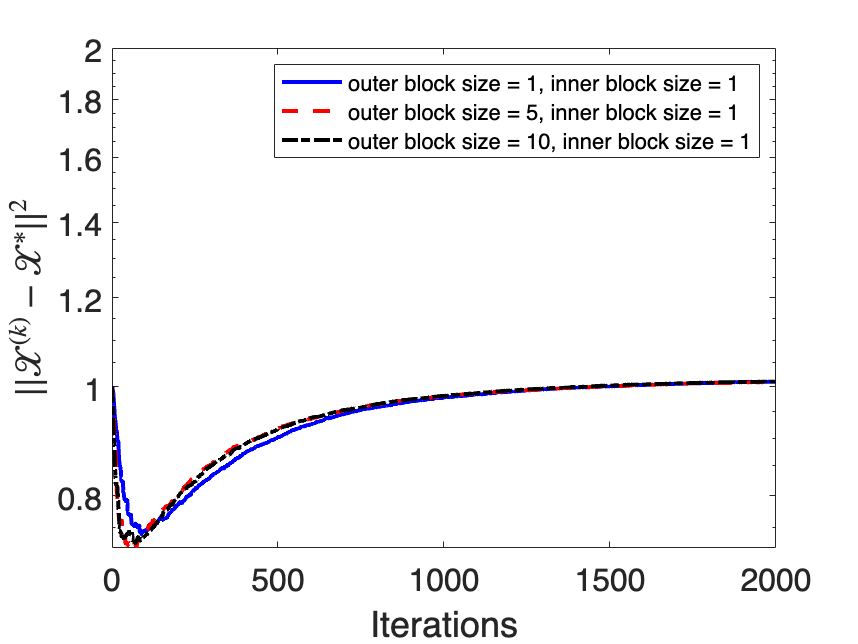

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
num_its = 2000; %num iterations
num_runs = 1;
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = [1,5,10,15]; %remember that the updates only make sense for block size <= number of columns

errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
norms = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

sum_ln_errs = ln_errs;
ave_ln_errs = sum_ln_errs;
in_block_size = 0;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs(i,:,k),res_errs(i,:,k),ln_errs(i,:,k),res_ln_errs(i,:,k),norms(i,:,k)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
        end
        sum_ln_errs(:,:,k) = sum_ln_errs(:,:,k)+ln_errs(:,:,k);
    end
    ave_ln_errs(:,:,k) = sum_ln_errs(:,:,k)/num_runs;
end
    %plot errors vs iterations
    clc
    figure(1);
    % % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},'LineWidth',2)

    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,1))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(1);
    legend(legendStrings, 'FontSize',11)

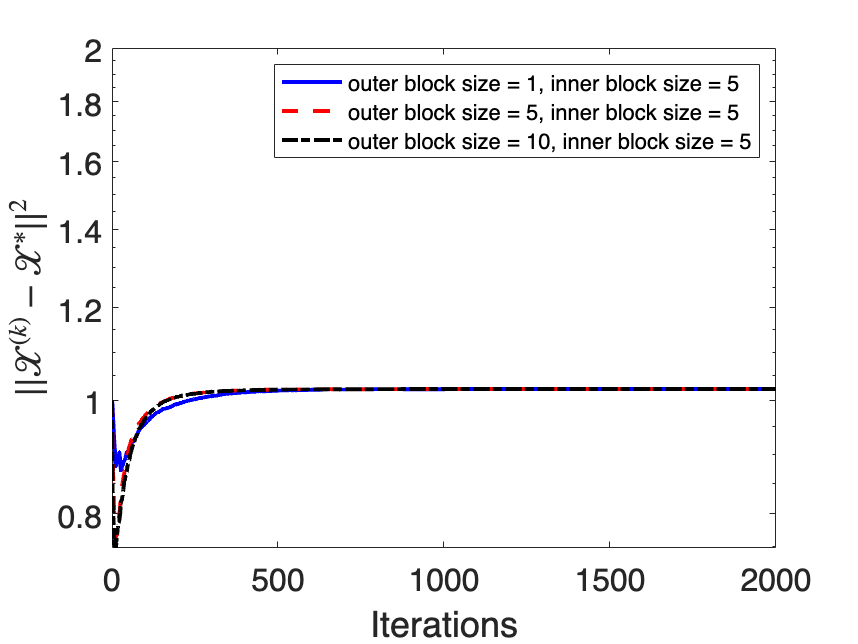

    % % hold off
    
    %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
    %plot errors vs iterations
    clc
    figure(2);
    % % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,2),line_styles{1},0:num_its,ave_ln_errs(2,:,2),line_styles{2},0:num_its,ave_ln_errs(3,:,2),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,2))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(2);
    legend(legendStrings, 'FontSize',11)

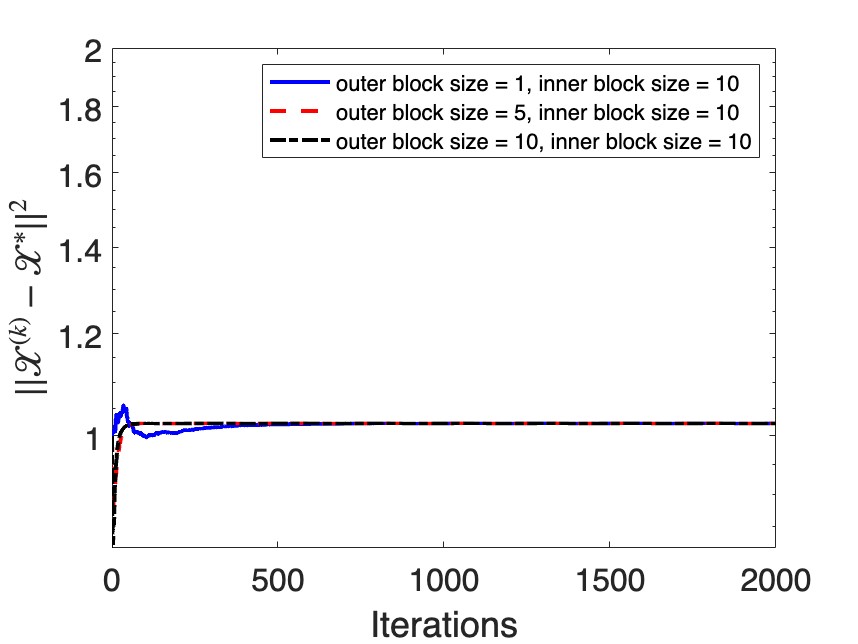

    % % hold off
   
    %plot errors vs iterations
    clc
    figure(3);
    % % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,3),line_styles{1},0:num_its,ave_ln_errs(2,:,3),line_styles{2},0:num_its,ave_ln_errs(3,:,3),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,3))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(3);
    legend(legendStrings, 'FontSize',11)

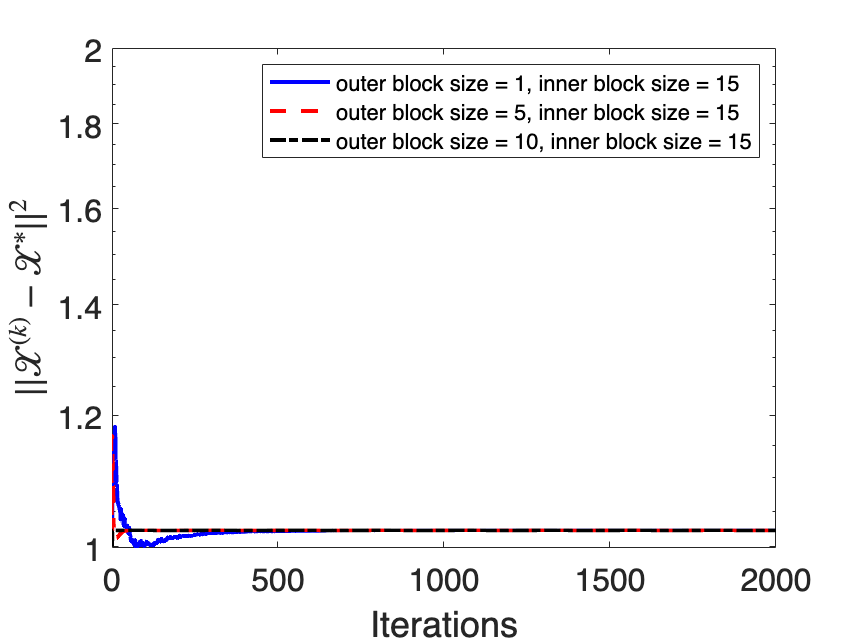

    % % hold off
  
    %plot errors vs iterations
    clc
    figure(4);
    % % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,4),line_styles{1},0:num_its,ave_ln_errs(2,:,4),line_styles{2},0:num_its,ave_ln_errs(3,:,4),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,4))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(4);
    legend(legendStrings, 'FontSize',11)

    % % hold off
     

2. U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)

%fixed:
p = 30;
n = 10;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_1 = 20;

%U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A underdetermined (m < m_1)--Works
m = 10;
m_2 = 5;

U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V);

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B = tprod(U, Z_ddagg);


Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

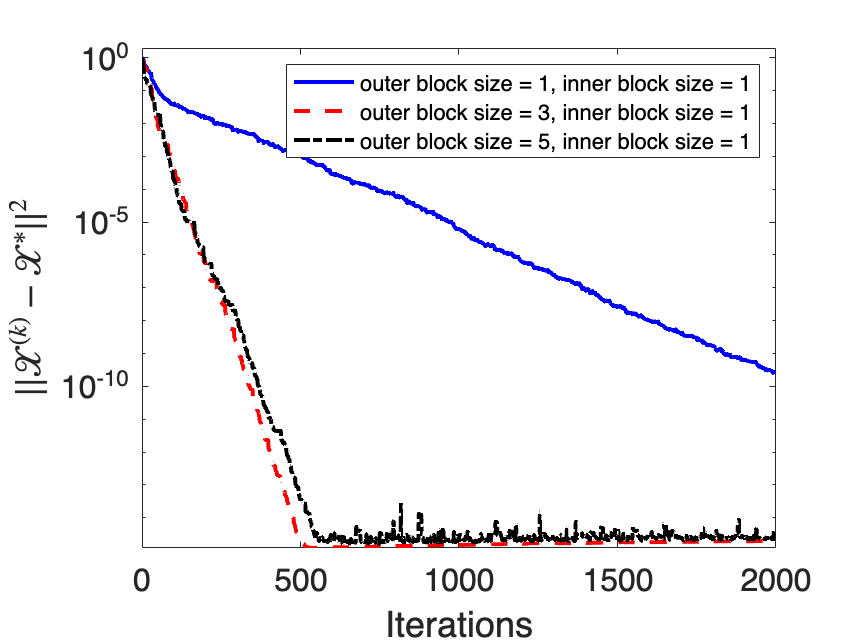

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
% num_its = 200; %num iterations
% num_runs = 10;
out_block_sizes = [1,3,5]; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = [1,3,5]; %remember that the updates only make sense for block size <= number of columns

errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
norms = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

sum_ln_errs = ln_errs;
ave_ln_errs = sum_ln_errs;
in_block_size = 0;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs(i,:,k),res_errs(i,:,k),ln_errs(i,:,k),res_ln_errs(i,:,k),norms(i,:,k)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
        end
        sum_ln_errs(:,:,k) = sum_ln_errs(:,:,k)+ln_errs(:,:,k);
    end
    ave_ln_errs(:,:,k) = sum_ln_errs(:,:,k)/num_runs;
end
    %plot errors vs iterations
    clc
    figure(5);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},'LineWidth',2)

    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,1))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(1);
    legend(legendStrings, 'FontSize',11)

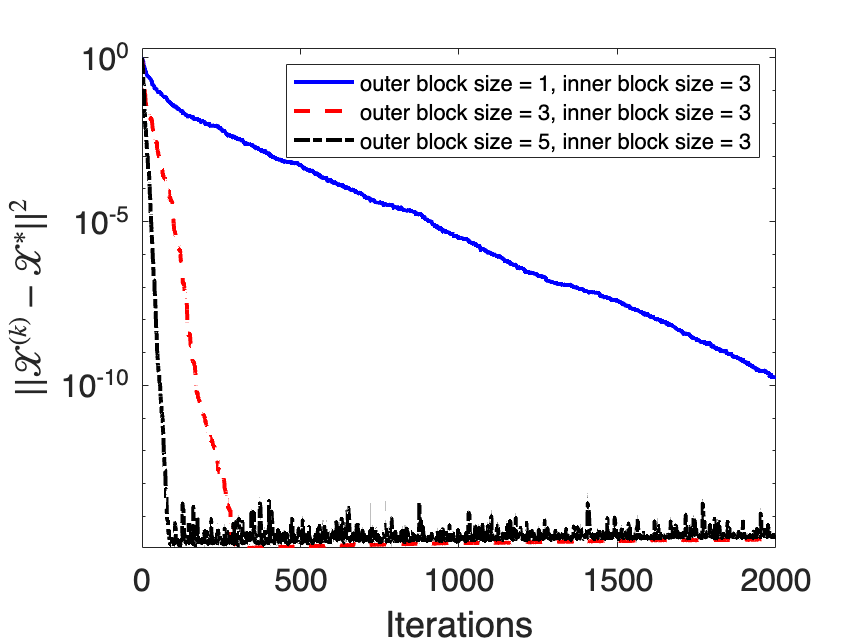

    % hold off
    
    %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
    %plot errors vs iterations
    clc
    figure(6);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,2),line_styles{1},0:num_its,ave_ln_errs(2,:,2),line_styles{2},0:num_its,ave_ln_errs(3,:,2),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,2))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(2);
    legend(legendStrings, 'FontSize',11)

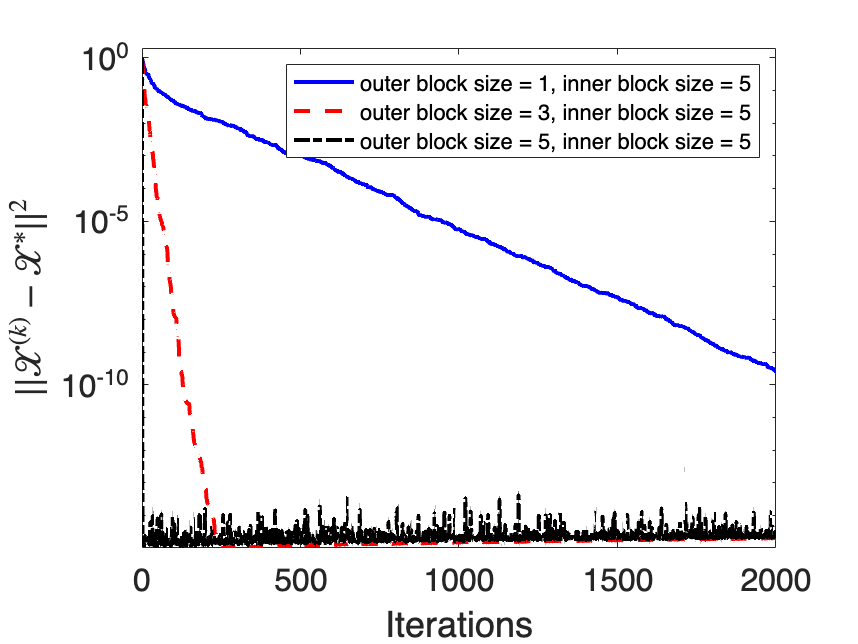

    % hold off
   
    %plot errors vs iterations
    clc
    figure(7);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,3),line_styles{1},0:num_its,ave_ln_errs(2,:,3),line_styles{2},0:num_its,ave_ln_errs(3,:,3),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,3))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(3);
    legend(legendStrings, 'FontSize',11)

    % hold off

3. U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A underdetermined (m < m_1)

%fixed:
p = 30;
n = 10;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_1 = 20;


%U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A underdetermined (m < m_1)--Works
m = 10;
m_2 = 25;


U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V);

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B = tprod(U, Z_ddagg);


Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

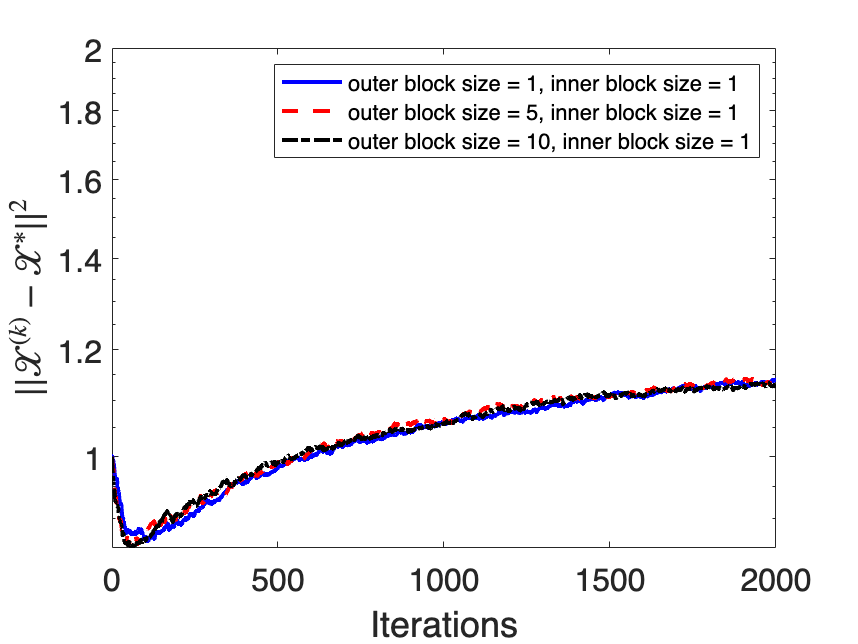

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
% num_its = 2000; %num iterations
% num_runs = 10;
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns (removed 20, is fine theoretically but in practice it shows a lot of oscillations)

errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
norms = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

sum_ln_errs = ln_errs;
ave_ln_errs = sum_ln_errs;
in_block_size = 0;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs(i,:,k),res_errs(i,:,k),ln_errs(i,:,k),res_ln_errs(i,:,k),norms(i,:,k)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
        end
        sum_ln_errs(:,:,k) = sum_ln_errs(:,:,k)+ln_errs(:,:,k);
    end
    ave_ln_errs(:,:,k) = sum_ln_errs(:,:,k)/num_runs;
        %plot errors vs iterations
end

    %plot errors vs iterations
    clc
    figure(8);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},'LineWidth',2)

    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,1))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(1);
    legend(legendStrings, 'FontSize',11)

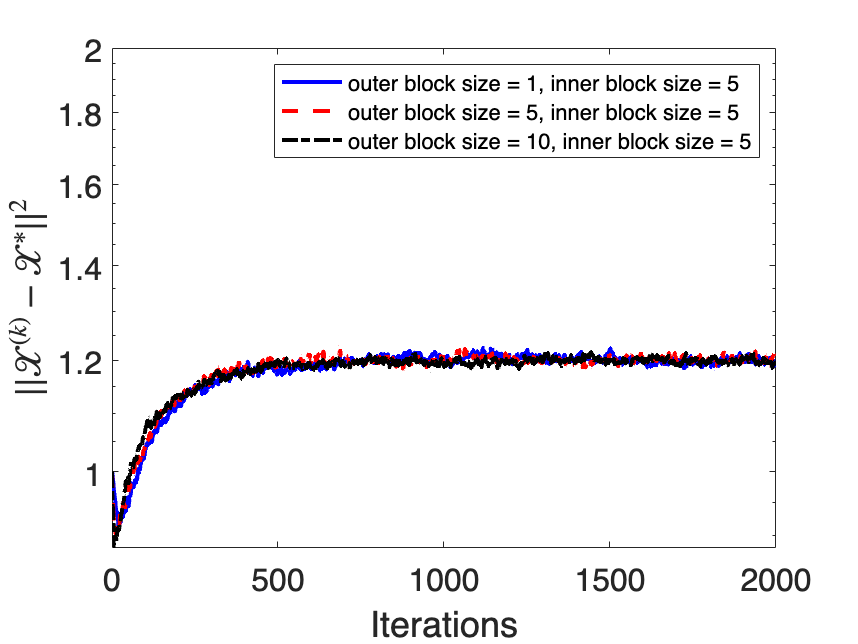

    % hold off
    
    %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
    %plot errors vs iterations
    clc
    figure(9);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,2),line_styles{1},0:num_its,ave_ln_errs(2,:,2),line_styles{2},0:num_its,ave_ln_errs(3,:,2),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,2))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(2);
    legend(legendStrings, 'FontSize',11)

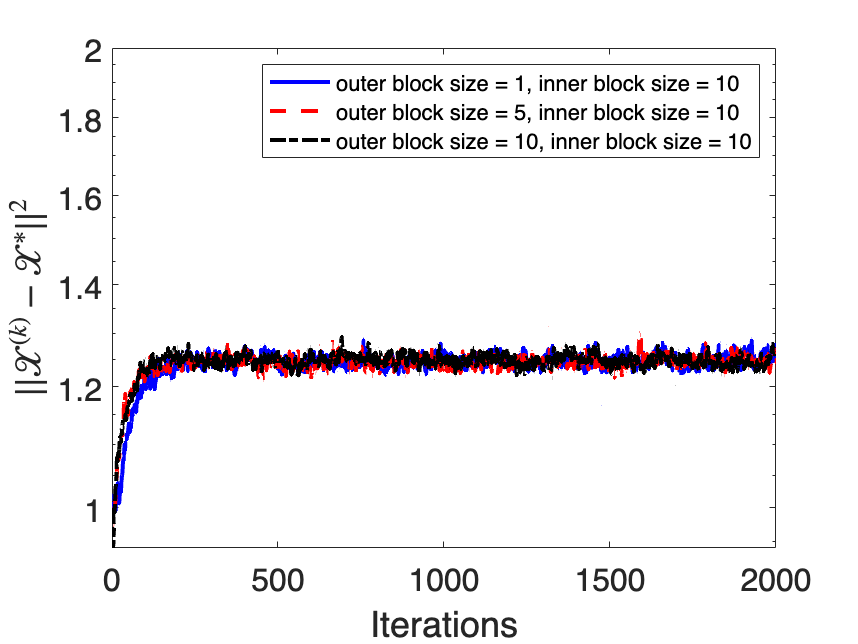

    % hold off
   
    %plot errors vs iterations
    clc
    figure(10);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,3),line_styles{1},0:num_its,ave_ln_errs(2,:,3),line_styles{2},0:num_its,ave_ln_errs(3,:,3),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,3))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(3);
    legend(legendStrings, 'FontSize',11)

    % hold off

4.U overdetermined (m < m_2) V overdetermined (m_1 > m_2), A overdetermined (m > m_1)

%fixed:
p = 30;
n = 10;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_1 = 20;


%U overdetermined (m < m_2) V overdetermined (m_1 > m_2), A overdetermined (m > m_1)--Works
m = 30;
m_2 = 25;


U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V);

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B = tprod(U, Z_ddagg);


Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

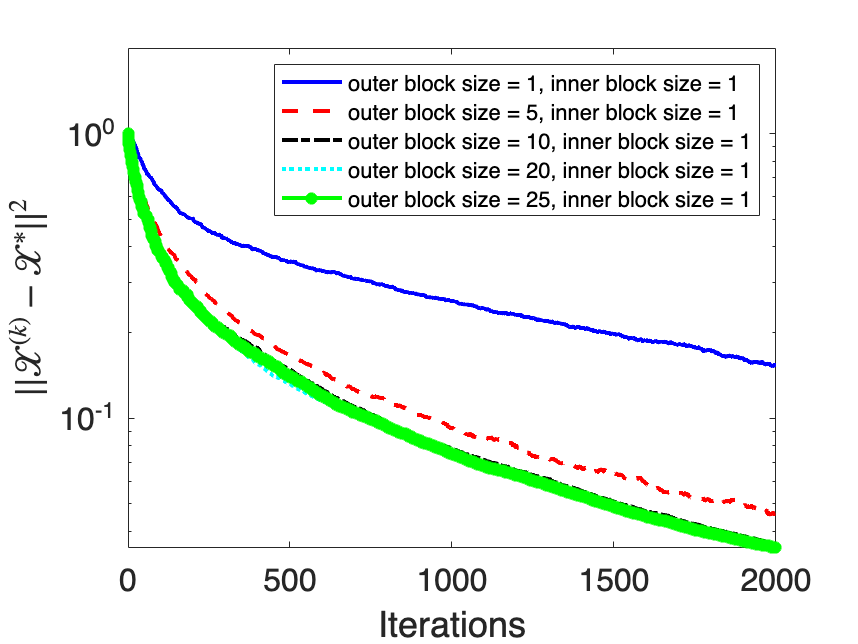

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
% num_its = 2000; %num iterations
% num_runs = 10;
out_block_sizes = [1,5,10,20,25]; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = [1,5,10,20]; %remember that the updates only make sense for block size <= number of columns (removed 20, is fine theoretically but in practice it shows a lot of oscillations)

errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
norms = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

sum_ln_errs = ln_errs;
ave_ln_errs = sum_ln_errs;
in_block_size = 0;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs(i,:,k),res_errs(i,:,k),ln_errs(i,:,k),res_ln_errs(i,:,k),norms(i,:,k)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
        end
        sum_ln_errs(:,:,k) = sum_ln_errs(:,:,k)+ln_errs(:,:,k);
    end
    ave_ln_errs(:,:,k) = sum_ln_errs(:,:,k)/num_runs;

end 
    %plot errors vs iterations
    clc
    figure(11);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},0:num_its,ave_ln_errs(5,:,1),line_styles{5},'LineWidth',2)

    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,1))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(1);
    legend(legendStrings, 'FontSize',11)

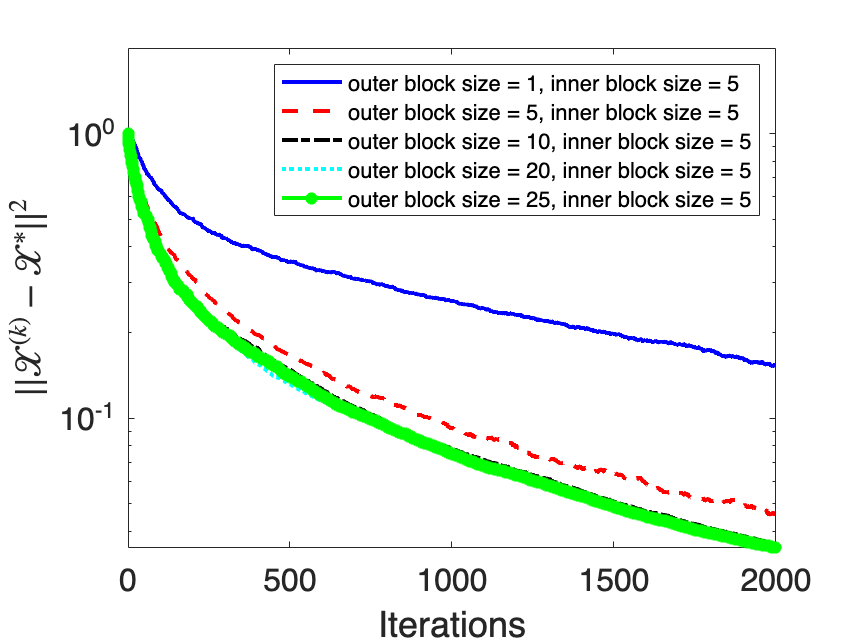

    % hold off
    
    %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
    %plot errors vs iterations
    clc
    figure(12);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},0:num_its,ave_ln_errs(5,:,1),line_styles{5},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,2))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(2);
    legend(legendStrings, 'FontSize',11)

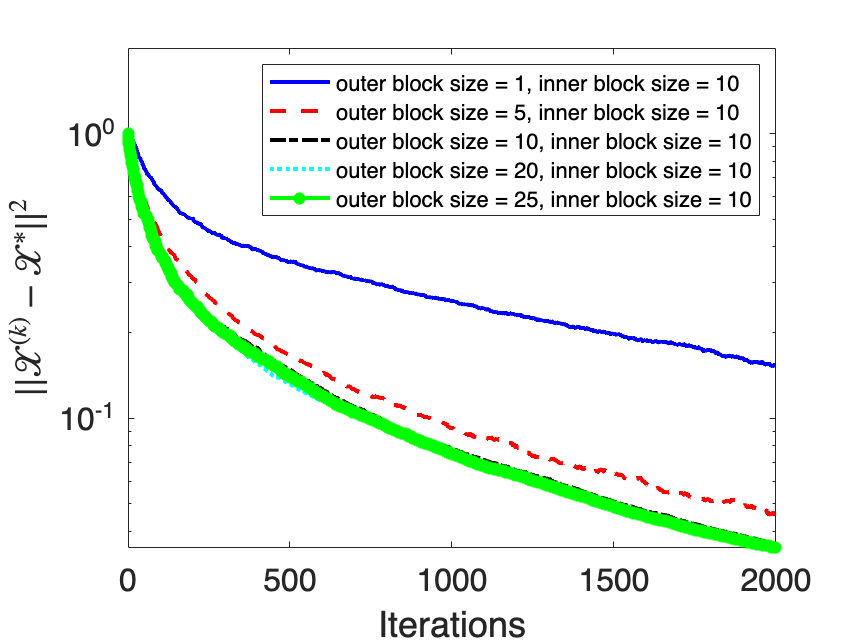

    % hold off
   
    %plot errors vs iterations
    clc
    figure(13);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},0:num_its,ave_ln_errs(5,:,1),line_styles{5},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,3))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(3);
    legend(legendStrings, 'FontSize',11)

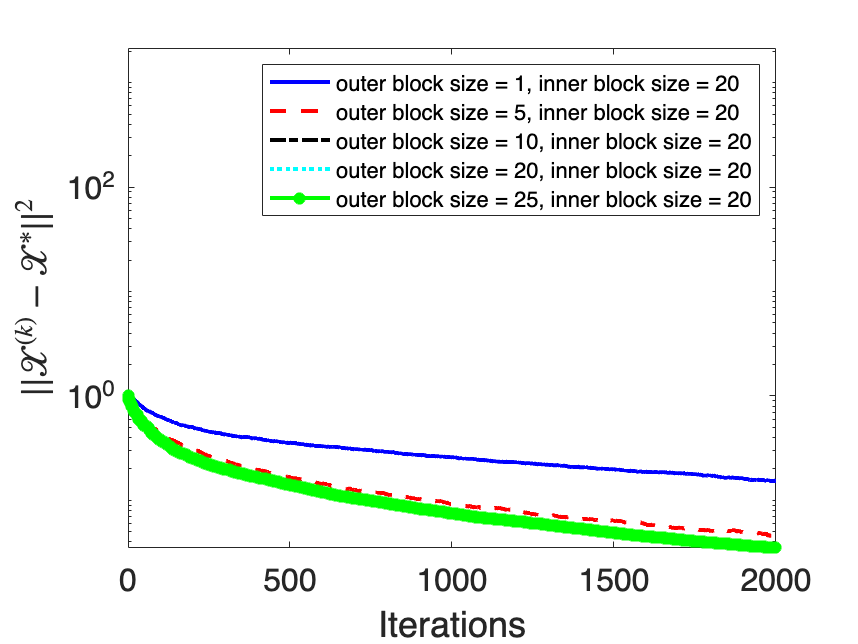

    % hold off
  
    %plot errors vs iterations
    clc
    figure(14);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},0:num_its,ave_ln_errs(5,:,1),line_styles{5},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,4))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(4);
    legend(legendStrings, 'FontSize',11)

    % hold off
     
 

5.U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A overdetermined (m > m_1)

%fixed:
p = 30;
n = 10;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_1 = 20;


%U overdetermined (m > m_2) V underdetermined (m_1 > m_2), A overdetermined (m > m_1)--Works
m = 30;
m_2 = 15;

U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V);

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B = tprod(U, Z_ddagg);


Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

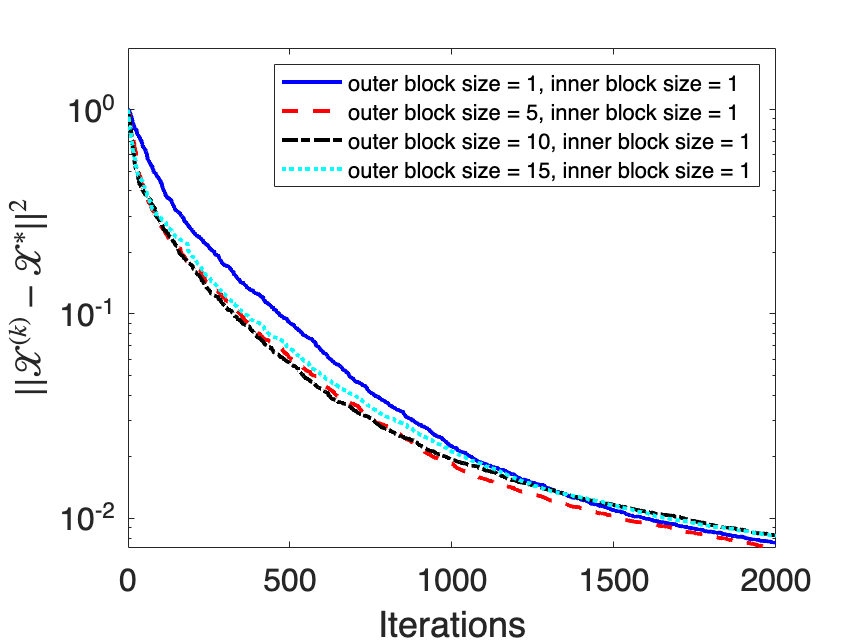

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
 % num_its = 200; %num iterations
 % num_runs = 1;
out_block_sizes = [1,5,10,15]; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = [1,5,10,15]; %remember that the updates only make sense for block size <= number of columns (removed 20, is fine theoretically but in practice it shows a lot of oscillations)

errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
norms = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

sum_ln_errs = ln_errs;
ave_ln_errs = sum_ln_errs;
in_block_size = 0;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs(i,:,k),res_errs(i,:,k),ln_errs(i,:,k),res_ln_errs(i,:,k),norms(i,:,k)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
        end
        sum_ln_errs(:,:,k) = sum_ln_errs(:,:,k)+ln_errs(:,:,k);
    end
    ave_ln_errs(:,:,k) = sum_ln_errs(:,:,k)/num_runs;
end

     %plot errors vs iterations
    clc
    figure(15);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},'LineWidth',2)

    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,1))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(1);
    legend(legendStrings, 'FontSize',11)

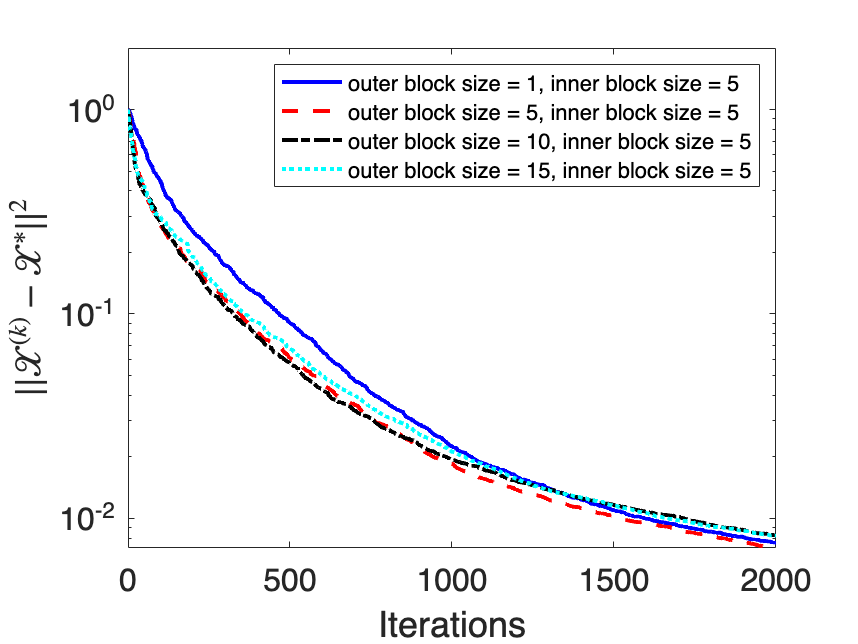

    % hold off
    
    %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
    %plot errors vs iterations
    clc
    figure(16);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,2))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(2);
    legend(legendStrings, 'FontSize',11)

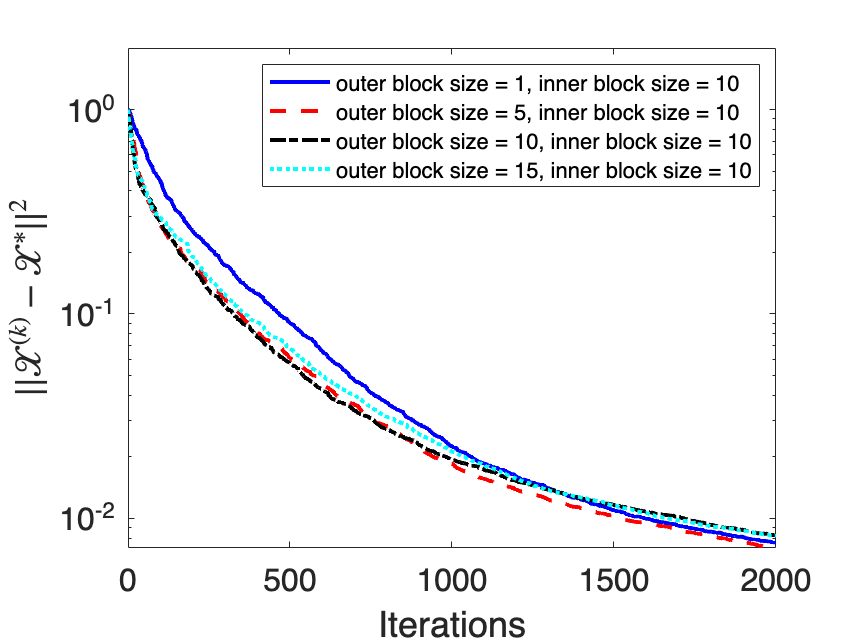

    % hold off
   
    %plot errors vs iterations
    clc
    figure(17);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,3))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(3);
    legend(legendStrings, 'FontSize',11)

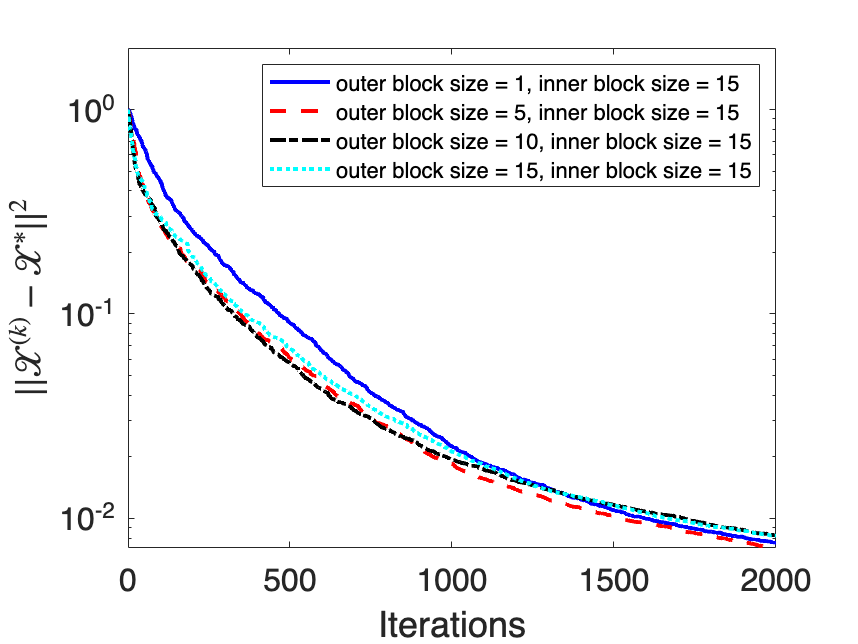

    % hold off
  
    %plot errors vs iterations
    clc
    figure(18);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},0:num_its,ave_ln_errs(4,:,1),line_styles{4},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,4))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(4);
    legend(legendStrings, 'FontSize',11)

    % hold off
 

6.U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A overdetermined (m > m_1)

%fixed:
p = 30;
n = 10;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_1 = 20;


%U underdetermined (m < m_2) V overdetermined (m_1 < m_2), A overdetermined (m > m_1)--Works
m = 30;
m_2 = 35;

U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V);

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B = tprod(U, Z_ddagg);


Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

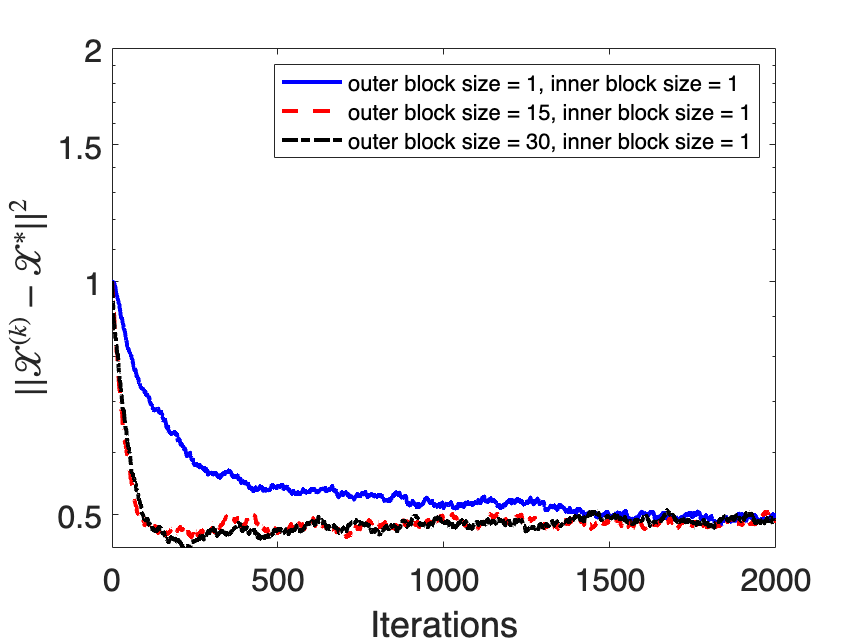

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
% num_its = 2000; %num iterations
% num_runs = 10;
out_block_sizes = [1,15,30]; %remember that the updates only make sense for block size <= number of columns
in_block_sizes = [1,10,20]; %remember that the updates only make sense for block size <= number of columns (removed 20, is fine theoretically but in practice it shows a lot of oscillations)

errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
norms = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));

sum_ln_errs = ln_errs;
ave_ln_errs = sum_ln_errs;
in_block_size = 0;
for k = 1:size(in_block_sizes,2)
    for j=1:num_runs   
        for i=1:size(out_block_sizes,2)
        out_block_size = out_block_sizes(i);
        in_block_size = in_block_sizes(k);
        [X,errs(i,:,k),res_errs(i,:,k),ln_errs(i,:,k),res_ln_errs(i,:,k),norms(i,:,k)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
        end
        sum_ln_errs(:,:,k) = sum_ln_errs(:,:,k)+ln_errs(:,:,k);
    end
    ave_ln_errs(:,:,k) = sum_ln_errs(:,:,k)/num_runs;
end
    %plot errors vs iterations
    clc
    figure(19);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,1),line_styles{1},0:num_its,ave_ln_errs(2,:,1),line_styles{2},0:num_its,ave_ln_errs(3,:,1),line_styles{3},'LineWidth',2)

    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,1))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(1);
    legend(legendStrings, 'FontSize',11)

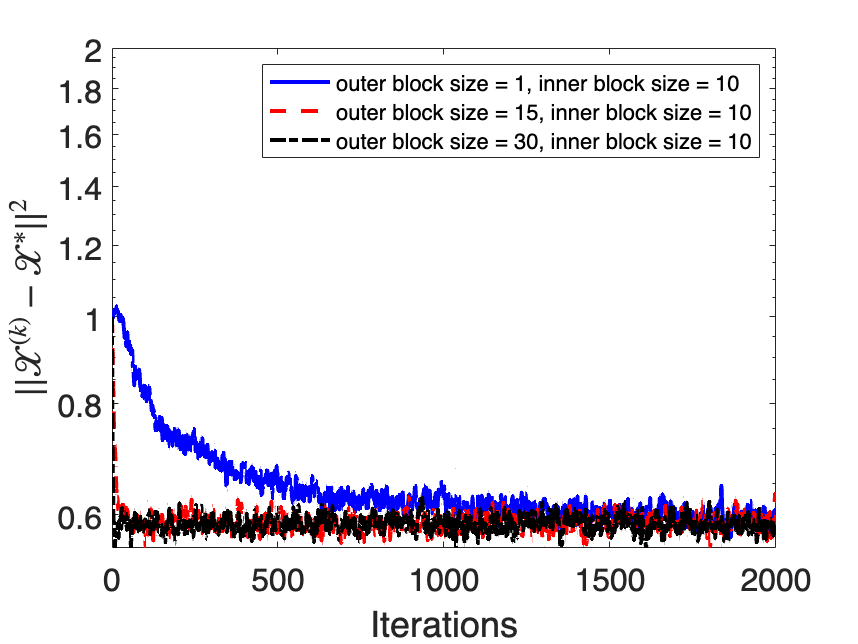

    % hold off
    
    %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
    %plot errors vs iterations
    clc
    figure(20);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,2),line_styles{1},0:num_its,ave_ln_errs(2,:,2),line_styles{2},0:num_its,ave_ln_errs(3,:,2),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,2))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(2);
    legend(legendStrings, 'FontSize',11)

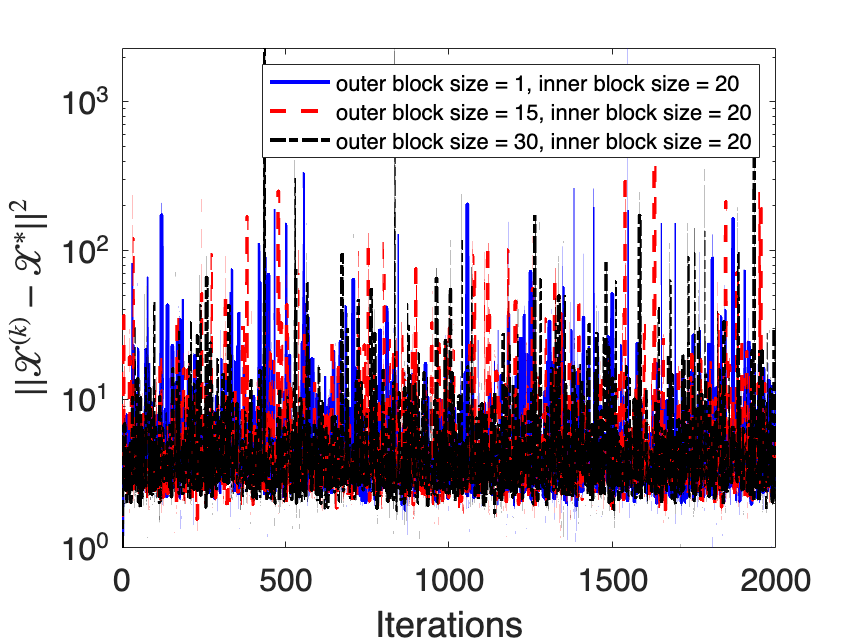

    % hold off
   
    %plot errors vs iterations
    clc
    figure(21);
    % hold on
    line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ave_ln_errs(1,:,3),line_styles{1},0:num_its,ave_ln_errs(2,:,3),line_styles{2},0:num_its,ave_ln_errs(3,:,3),line_styles{3},'LineWidth',2)
    set(gca,'FontSize',16)
    xlabel('Iterations','FontSize',18) 
    ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
    ylim([0,round(max(max(ave_ln_errs(:,:,3))),0)+1])
    % titleString = "Inner block size = " + in_block_sizes(k);
    % title(titleString);
    legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(3);
    legend(legendStrings, 'FontSize',11)

    % hold off

 

7. U overdetermined (m = m_2) V overdetermined (m_1 = m_2), A overdetermined (m = m_1)

% %fixed:
% p = 30;
% n = 10;
% 
% % X_true is 20 x 10 x 30
% %m determines whether A = UV is underdetermined or overdetermined
% %m_1 determinex whether V is underdetermined or overdetermined
% %m_2 is like k in Ma & Needell's paper
% m_1 = 20;
% 
% %U overdetermined (m = m_2) V overdetermined (m_1 = m_2), A overdetermined (m = m_1)--Works
% m = 20;
% m_2 = 20;
% 
% %generate tensors
% U = randn(m, m_2,p);
% V = randn(m_2,m_1,p);
% A=tprod(U,V); 
% 
% X_true = randn(m_1,n,p);
% 
% 
% %generate consistent measurements
% B = tprod(A, X_true);
% 

Now, we run FacTBRK with a variety of choices of outer block sizes on this consistent system.

% X_0 = randn(size(X_true));
% X_LN = tprod(tpinv(A),B);
% X_LN2 = tprod(tprod(tpinv(V),tpinv(U)),B);
% norm(X_LN(:)-X_LN2(:))
% norm(X_LN(:)-X_true(:))
% % num_its = 2000; %num iterations
% % num_runs = 10;
% out_block_sizes = [1,10,20]; %remember that the updates only make sense for block size <= number of columns
% in_block_sizes = [1,10,20]; %remember that the updates only make sense for block size <= number of columns (removed 20, is fine theoretically but in practice it shows a lot of oscillations)
% 
% errs = zeros(size(out_block_sizes,2),num_its+1,size(in_block_sizes,2));
% res_errs = zeros(size(out_block_sizes,2),num_its+1);
% ln_errs = zeros(size(out_block_sizes,2),num_its+1);
% res_ln_errs = zeros(size(out_block_sizes,2),num_its+1);
% norms = zeros(size(out_block_sizes,2),num_its+1);
% 
% sum_errs = errs;
% ave_errs = sum_errs;
% in_block_size = 0;
% for k = 1:size(in_block_sizes,2)
%     for j=1:num_runs   
%         for i=1:size(out_block_sizes,2)
%         out_block_size = out_block_sizes(i);
%         in_block_size = in_block_sizes(k);
%         [X,errs(i,:,k),res_errs(i,:),ln_errs(i,:),res_ln_errs(i,:),norms(i,:)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
%         end
%         sum_errs(:,:,k) = sum_errs(:,:,k)+errs(:,:,k);
%     end
%     ave_errs(:,:,k) = sum_errs(:,:,k)/num_runs;
%         %plot errors vs iterations
%     clc
%     figure();
%     % hold on
%     line_styles = {'b-','r--','k-.','c:','g-*','m-+','y-x','-o','-pentagram','-diamond'};
%     for i = 1:size(out_block_sizes,2)
%         i;
%         semilogy(0:num_its,ave_errs(i,:,k),line_styles{i},'LineWidth',2)
%     end
%     set(gca,'FontSize',16)
%     xlabel('Iterations','FontSize',18) 
%     ylabel('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','Interpreter','latex','FontSize',18) 
%     ylim([0,round(max(max(ave_errs(:,:,k))),0)+1])
%     % titleString = "Inner block size = " + in_block_sizes(k);
%     % title(titleString);
%     legendStrings = "outer block size = " + string(out_block_sizes)+ ", inner block size = "+ in_block_sizes(k);
%     legend(legendStrings, 'FontSize',11)
%     % hold off
% 
%     %saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");
% 
% end
% % 